close all
clear all

A=[1 0.2;0 1];
B=[0;0.2];
C=[0.6 -0.2];
D=0;

n=size(A,2);
m=size(B,2);

% Weightings in the quadratic cost
Q=C'*C;
R=eye(m,m); % to be tuned
%solution of the Riccati equation and the associated stabilizing gain (G)
[P,L,G] = dare(A,B,Q,R);

Hx=[eye(n,n);   -eye(n,n)]; % Matrices describing the state constraints
Hu=[eye(m,m);     -eye(m,m)];% Matrices describing the input constraints

Wx=1*ones(2*n,1); %the right hand side of the state constraints
Wu=0.1*ones(2*m,1); %the right hand side of the input constraints

Q1 Construction of Maximal output admissible set

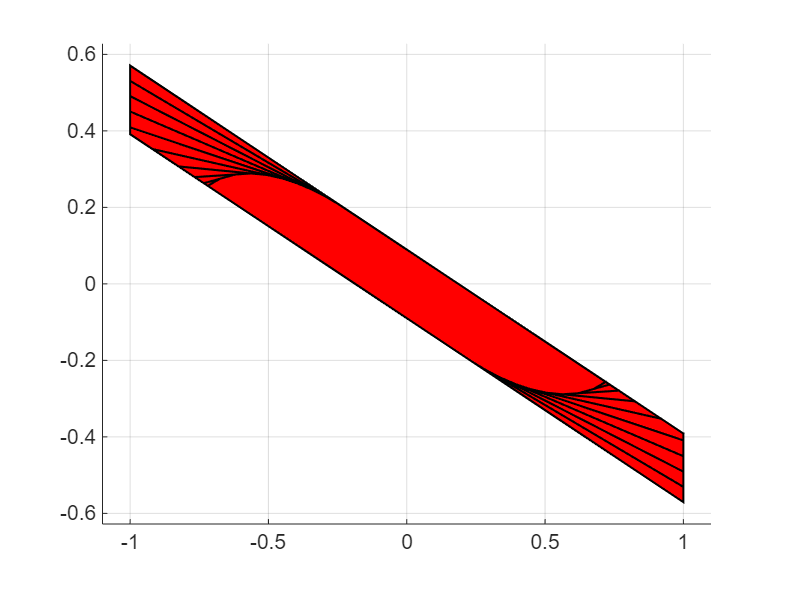

stop = logical
   1


figure
hold on
%O_0
Htemp = [Hx ; Hu*G];
Wtemp = [Wx ; Wu];
Oi = Polyhedron(Htemp, Wtemp);  % Why this is the set of constrained to be considered?
Oi.plot();

%iterative phase
i = 1;
stop = false;
Acl = A - B*G;
while(stop == false)

    %!!!!!!!! to be completed - START !!!!!!!!!
    %
    %
    %
    New_Set=intersect(Oi,Polyhedron(Oi.A*Acl,Oi.b));
        %!!!!!!!! to be completed -  END  !!!!!!!!

    if (New_Set == Oi)
        stop = true
    end

    Oi = New_Set;
    Oi.plot('alpha',0.1);
    i = i + 1;
end

From the plot it is obvious that graphically the positive invariance of the resulting set O infinity.

Hf = Oi.A;
Wf = Oi.b;

figure % graphically test the result in terms of invariance
hold on
Oinf = Polyhedron(Hf, Wf)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  20 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


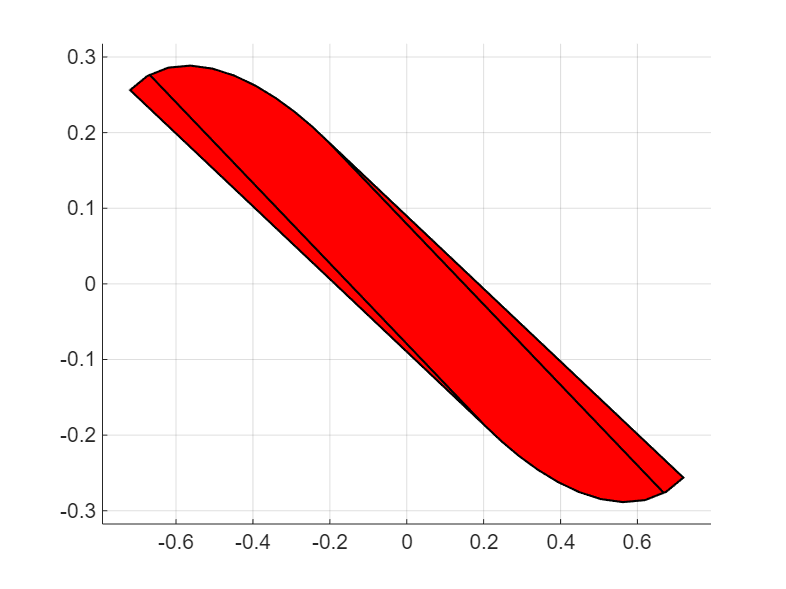

Oinf.plot()
Oplus=Acl*Oinf;
Oplus.plot;

The algorithm iteratively constructs the maximal output admissible set , ensuring all state and input constraints are satisfied under closed-loop dynamics. Starting with an initial set, defined by the constraints, the procedure refines the set by intersecting it with its forward image at each step. The convergence of the sets is evident from the plots, where Oi stabilizes to a fixed shape, representing Oinf. Graphical verification confirms that Oinf is positively invariant, as its forward image lies entirely within itself. This ensures the system's ability to stabilize at the origin while adhering to constraints, providing guarantees for MPC stability and feasibility.

Q2. MPC with input and state constraints

Set_X=Polyhedron(Hx,Wx);
Set_U=Polyhedron(Hu,Wu);

N=5;% prediction horizon

U_vect = sdpvar(repmat(m,1,N),repmat(1,1,N));
X_vect = sdpvar(repmat(n,1,N+1),repmat(1,1,N+1));

constraints_MPC = [];
objective_MPC = 0;
for k = 1:N
    constraints_MPC = [constraints_MPC, X_vect{k+1} == A*X_vect{k} + B*U_vect{k}];
    constraints_MPC = [constraints_MPC, Hx*X_vect{k+1}<=Wx];
    constraints_MPC = [constraints_MPC, Hx*X_vect{k+1}<=Wx];    %complete with the input constriants!!
    objective_MPC = objective_MPC + ((X_vect{k+1})'*C'*C*(X_vect{k+1}))+ (U_vect{k}'*U_vect{k});
end
objective_MPC = objective_MPC + ((X_vect{N+1})'*P*(X_vect{N+1}));
%!!!!!!!! to be completed - START !!!!!!!!!
constraints_MPC = [constraints_MPC, Hf*X_vect{N+1}<=Wf];% complete with the terminal constraints and the terminal cost function
%!!!!!!!! to be completed -  END  !!!!!!!!

ops = sdpsettings('verbose',2,'solver','');%sdpsettings('solver','cplex')
controller = optimizer(constraints_MPC, objective_MPC,ops,X_vect{1},[U_vect{:}]);




X = [0.84;-0.25] % initial state x(0)

X =     0.8400
   -0.2500



tsim=100

tsim = 100

Umem = [];
for i = 1:tsim
    U = controller{X(:,end)};
    X = [X A*X(:,end) + B*U(1:m)];%(-G)*X(:,end)
    Umem = [Umem U(1:m)];
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

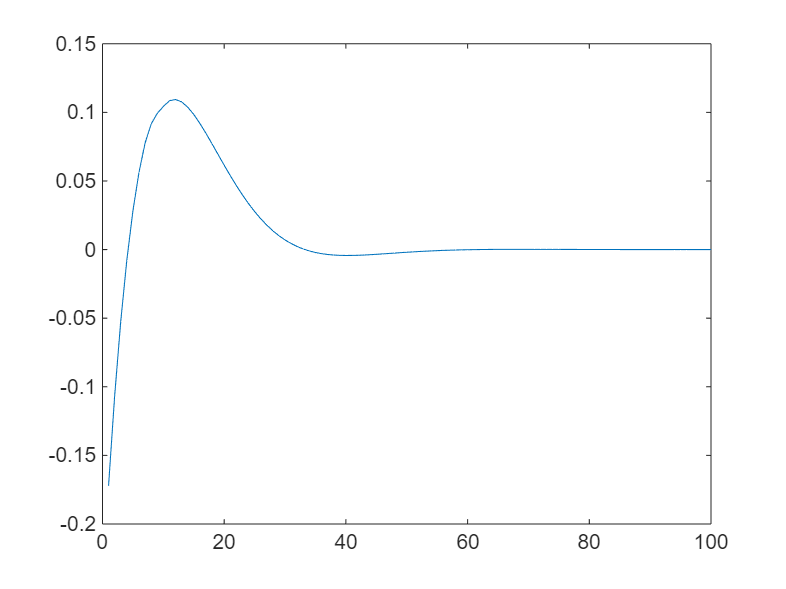


figure
plot(Umem(1,:))

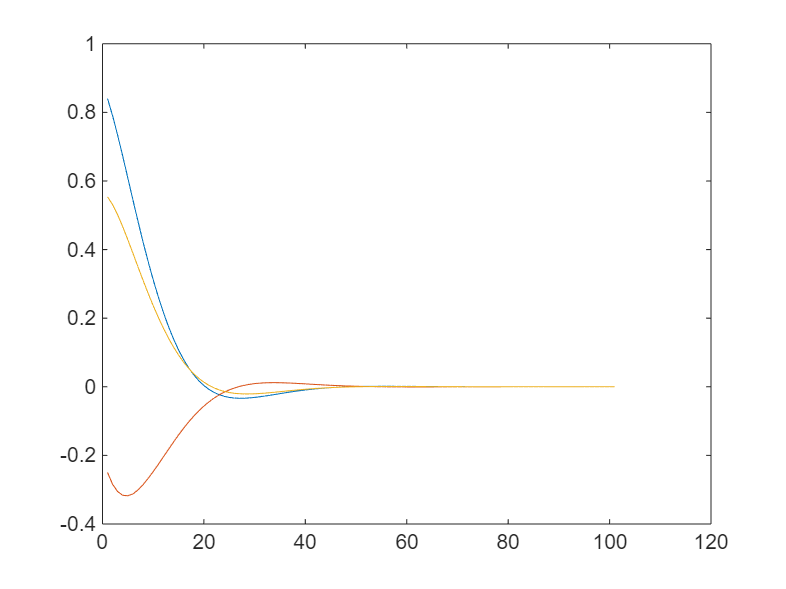

figure
plot(X(1,:));
hold on
plot(X(2,:));
plot(C*X)

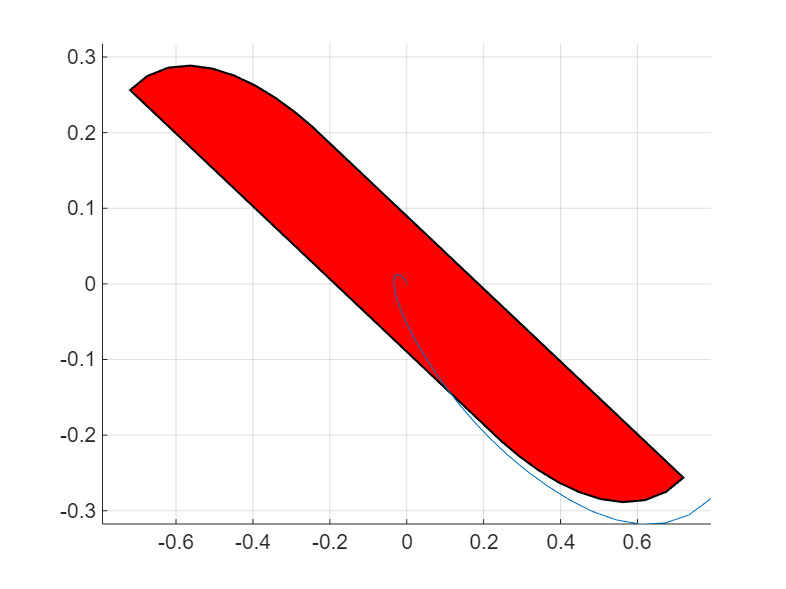


figure
% test of invaraince
Oinf.plot()
hold on
plot(X(1,:),X(2,:));

Incorporating state and input constraints ensures the system operates safely throughout the prediction horizon. The objective function balances state deviations and input effort. With a prediction horizon of N= 5, the MPC predicts future states and computes optimal control inputs. The terminal constraint ensures stability, maintaining a final state within defined bounds. The optimizer finds the best control inputs by considering constraints and minimizing the objective function. The closed-loop simulation demonstrates the system’s ability to track desired states while adhering to constraints, ensuring robust control performance.

## Q3. Feasible domain for the MPC controller and the comparison with the maimal controllable set

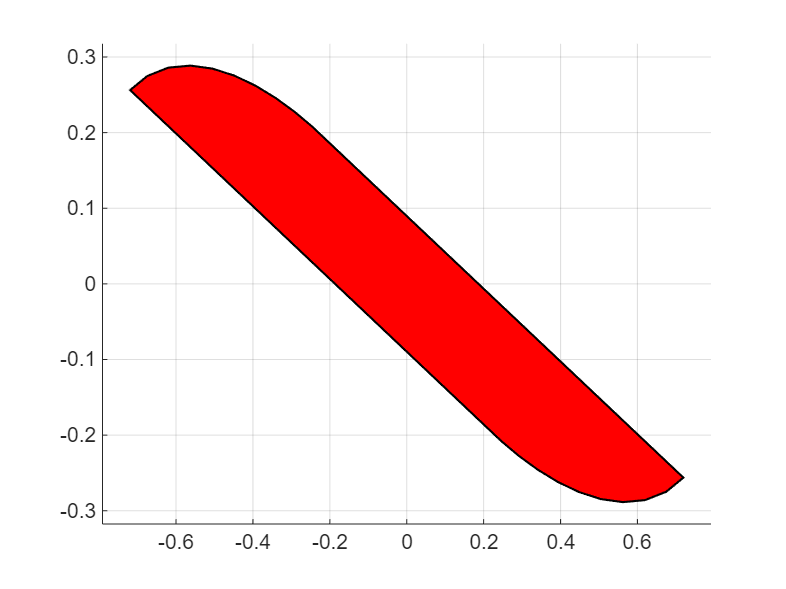

figure
Oinf.plot()
Control_Set_X=Oinf;
hold on
for i=1:25

    %!!!!!!!! to be completed - START !!!!!!!!!
    ;% complete with the construction of a new set according to the iterative scheme available in slide 62
    %!!!!!!!! to be completed -  END  !!!!!!!!
    C_new = intersect(Control_Set_X, Polyhedron(Hf * Acl, Wf)); 

    C_new.plot('alpha',0.1);

    if(C_new == Control_Set_X)
        break
    else
        Control_Set_X=C_new;
    end
end

The MPC controller's feasible domain was constructed iteratively, starting with X0� and progressing through the prediction horizon N. Each iteration involved intersecting the current set with controlled invariant sets to approximate the maximal invariant set. This approach provides insight into how the feasible domain evolves over time, balancing performance and computational complexity. As the prediction horizon increases, the computational effort rises, reflecting the trade-off between accuracy and processing load.